计算高阻抗表面上表面波的色散关系

作者：FTT

创建日期：2024.12.11

clear
clc
close all

超表面参数

C = 0.05e-12; %表面电容
L = 2e-9; %表面电感

常量

eps0 = 8.854e-12; %真空介电常数
mu0 = 4*pi*1e-7; %真空磁导率
eta0 = sqrt(mu0/eps0); %自由空间波阻抗
c0 = 1/sqrt(mu0*eps0); %真空光速
f = linspace(0, 30e9, 1000); %扫描频率
omega = 2*pi*f;

表面阻抗

Zs = 1i*omega*L./(1-omega.^2*L*C); %论文中式（16）

谐振频率

Omega0 = 1/sqrt(L*C);
[~, Omega0Index] = min(abs(omega-Omega0));

计算TM模的色散关系

kTM = omega(1:Omega0Index)./c0.*sqrt(1-Zs(1:Omega0Index).^2/eta0^2); %论文中式（19）

计算TE模的色散关系

kTE = omega(Omega0Index:end)./c0.*sqrt(1-eta0^2./Zs(Omega0Index:end).^2); %论文中式（20）

真空波数

k0 = omega/c0;

绘制色散关系

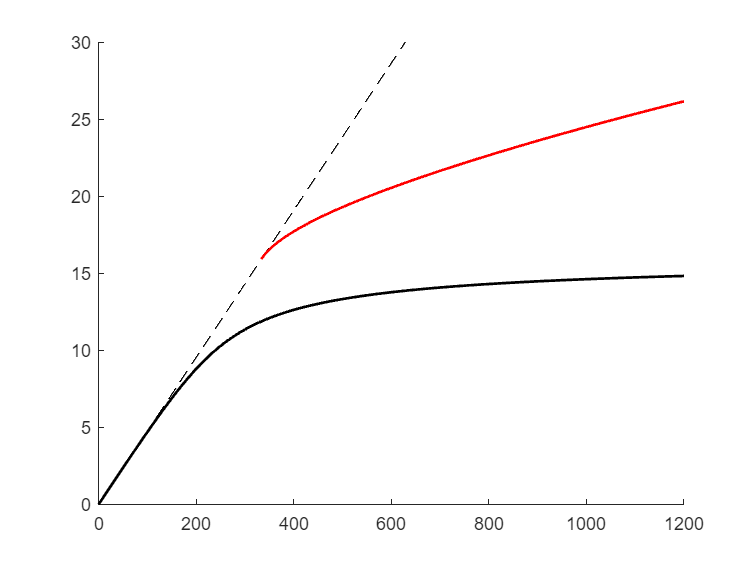

figure;
hold on
plot(real(k0), f/1e9, 'k--')
plot(real(kTM), f(1:Omega0Index)/1e9, 'k', 'LineWidth', 1.5)
plot(real(kTE), f(Omega0Index:end)/1e9, 'r-', 'LineWidth', 1.5)
xlim([0 1200])
ylim([0 30])